# Lesson I.2:   Small Linear Systems (F24)

The previous lesson made the key observation that the coefficients for expanding one vector as a linear combination of other vectors satisfy a system of linear equations.    For this reason and for many other applications, this lesson reviews the basic facts regarding small linear systems with a limited number of variables.

Solving systems of linear equations is familiar from high school algebra.   The [New Jersey Student Learning Standards for Mathematics](https://www.nj.gov/education/standards/math/Docs/2016NJSLS-M_HighSchool.pdf) suggests that high school graduates in New Jersey are able to "solve systems of linear equations exactly and approximately (e.g., with graphs), focusing on pairs of linear equations in two variables."   High school algebra generally focusses on small numbers of equations and variables.    In Math 337 this focus is extended to an arbitrary number of equations and variables.  We begin with a review in ten examples of linear systems with two or three unknown variables.       With a small number of unknowns, the solutions can be visualized as sets in two- or three-dimensional space allowing us to build geometric intuition regarding the structure of the solution set.    As we move to systems with more unknown variables, we will seek to reformulate this intuition in algorithmic and algebraic terms allowing us to apply it to high dimensional spaces where visualization is difficult at best.

### Basic Nomenclature of Linear Systems:

A ***linear equation in two unknowns*** $x$ and $y$ has the form:  

                 $\textrm{ax}+\textrm{by}=c$                        (augmented matrix: $\left[\matrix{a & b & c}\right]
$).

A ***linear equation in three unknowns*** $x$, $y$ and $z$ has the form: 

                  $\textrm{ax}+\textrm{by}+\textrm{cz}=d$               (augmented matrix: $\left[\matrix{a & b & c& d}\right]
$).

Generally the solution set of one linear equation with $n$ unknowns is a ***hyperplane*** of dimension $n-1$.   That is, a linear equation with two unknowns typically represents a line in the plane (see examples 6 & 7 below for exceptions), and a linear equation with three unknowns typically represents a plane in space.     

An important way of writing and manipulating linear systems is as ***augmented matrices*** which represent the linear system concisely as a rectangular array of numbers (a matrix). 

### Ten Examples with Two or Three unknowns:

#### Example I.2.1: (1 equation with 2 unknowns -- infinitely many solutions)   


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{\quad
\matrix{
x&+&y&=&3} \right .$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\quad
\left [ \matrix{ 1 & 1 & 3 }\right]$$


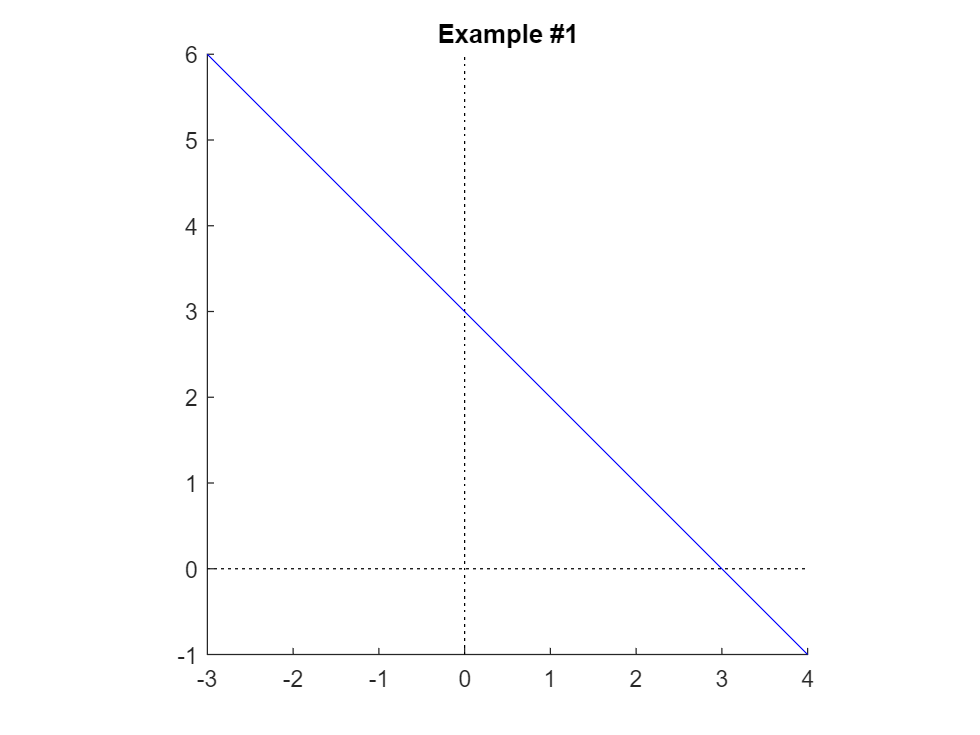

plot2unknowns([1 1 3],[-3 4 -1 6],1)     % plots the lines defined by the equation(s) of the linear system in a given window


$$\quad\qquad\qquad\qquad 
\text{solution set:  }\quad \left\{\left[\matrix{ x \cr 3-x}\right]~:~x \in{\mathbb R} \right\}~=~\left\{\left[\matrix{3-y\cr y}\right]~:~ y\in{\mathbb R}\right\}$$


**    Notes:**

- A linear equation with two unknowns, $ax+by=c$, represents a ***line*** if either $a\ne0$ or $b\ne 0$. 

#### Example I.2.2: (2 equations with 2 unknowns -- unique solution)


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{
\matrix{
x&+&y&=&3\cr
-x&+&y&=&5} \right .$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\quad
\left[\matrix{
1 & 1 & 3 \cr -1 & 1 & 5 }\right]$$


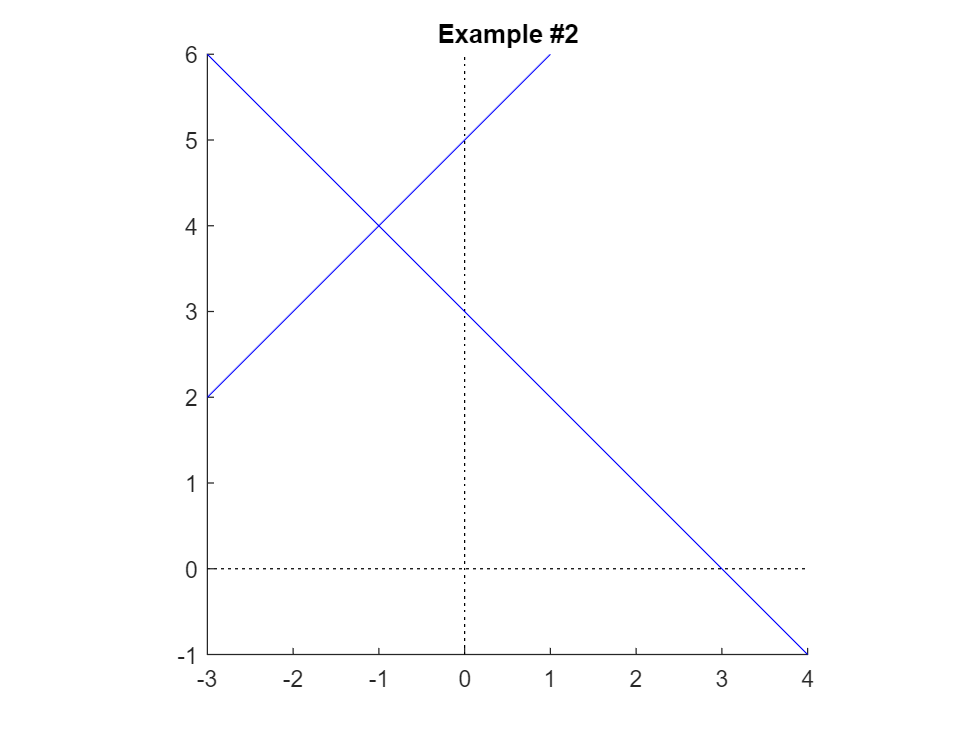

plot2unknowns([1 1 3; -1 1 5],[-3 4 -1 6],2)


$$\qquad\qquad\qquad\qquad
\text{solution set:}\quad 
\left\{~\left[\matrix{-1\cr 4}\right]~\right\}$$


#### **    Notes:**

- Systems of two equations with two unknowns typically represent two lines intersecting in a point (the unique solution).

#### Example I.2.3: (3 equations with 2 unknowns -- a lucky unique solution)


$$\qquad\qquad\qquad\qquad
\text{linear system:  }\quad \left\{
\matrix{
x&+&y&=&3\cr
-x&+&y&=&5 \cr
3x&+&2y&=&5} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\quad
\left[\matrix{
1 & 1 & 3 \cr -1 & 1 & 5\cr 3 & 2 & 5 }\right]$$


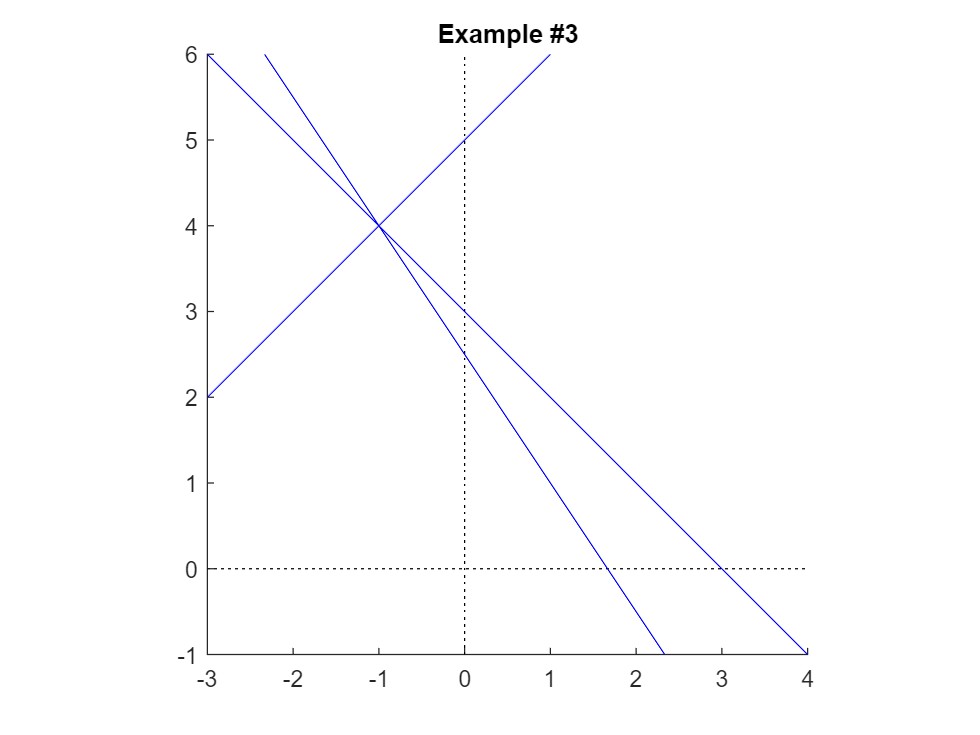

plot2unknowns([1 1 3; -1 1 5; 3 2 5],[-3 4 -1 6],3)


$$\qquad\qquad\qquad\qquad
\text{solution set:}\quad 
\left\{~\left[\matrix{-1\cr 2}\right]~\right\}$$


    **Notes:**

- While three lines typically would not have a common point of intersection, here we have a solution despite the number of equations exceeding the number of unknowns.

#### Example I.2.4: (2 equations with 2 unknowns -- no solution)


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{
\matrix{
2x&+&y&=&3\cr
2x&+&y&=&4} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\qquad
\left[\matrix{
2 & 1 & 3 \cr 2 & 1 & 4 }\right]$$


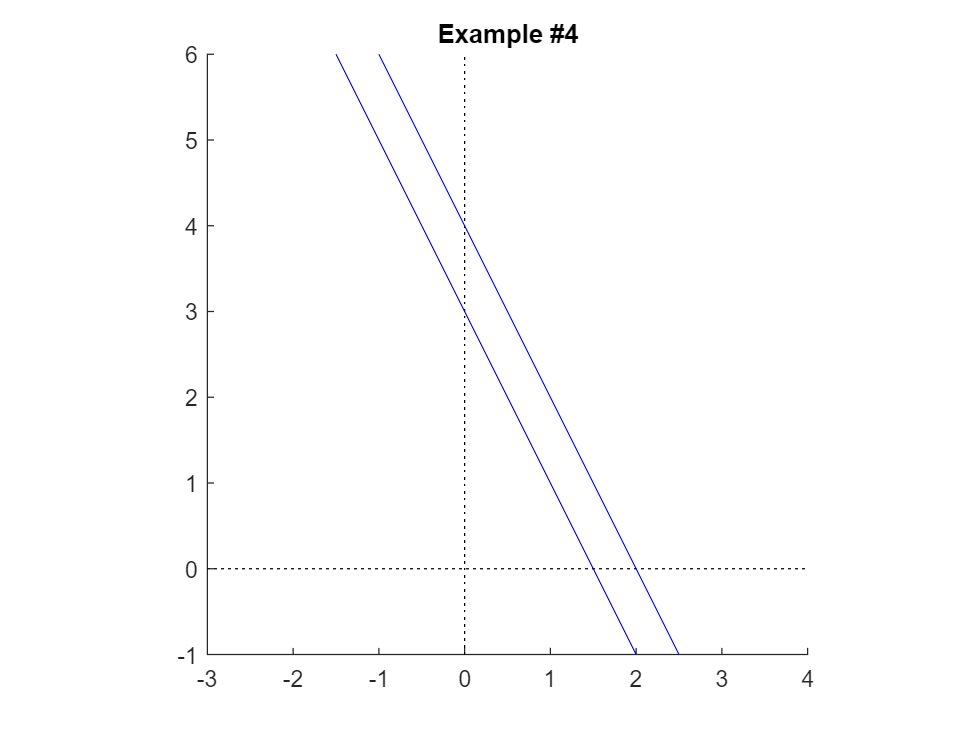

plot2unknowns([2 1 3; 2 1 4],[-3 4 -1 6],4)

$\qquad\qquad\qquad\qquad
\text{solution set:  }\quad
\emptyset~=~\left \{~\right\}$        (two common notations for an empty set)

    **Notes:**

- Parallel lines lack an intersection; hence, the solution set is empty.

#### Example I.2.5: (2 equations with 2 unknowns -- infinitely many solutions}


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{
\matrix{
3x&+&2y&=&7\cr
6x&+&4y&=&14} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\qquad
\left[\matrix{
3 & 2 & 7 \cr 6 & 4 & 14 }\right]$$


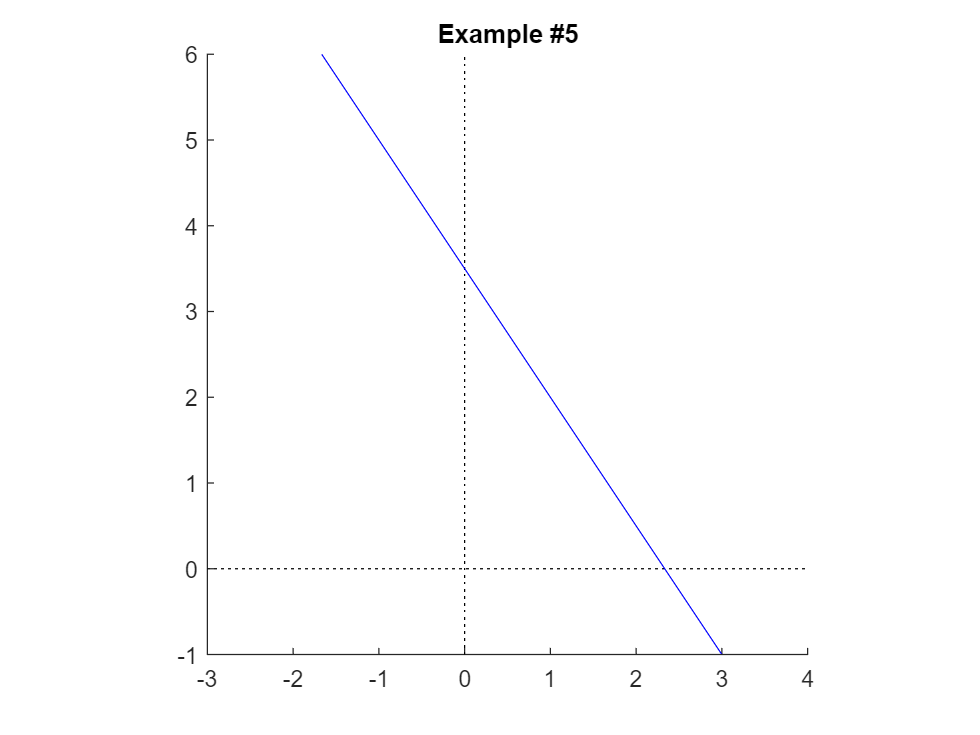

plot2unknowns([3 2 7; 6 4 14],[-3 4 -1 6],5)


$$\qquad\qquad\qquad\qquad
\text{solution set:  }\quad
\left\{~\left[\matrix{x \cr \frac{7-3x}{2} }\right]~:~x\in{\mathbb R}\right\}~=~
\left\{~\left[\matrix{\frac{7-2y}{3}\cr y}\right]~:~y\in{\mathbb R}\right\}$$


    **Notes:**

- Two simultaneous lines intersect at infinitely many points.

- Infinite sets, such as lines, can typically be parameterized in many ways.

#### Example I.2.6: (1 equation with 2 unknowns -- not a line, infinitely many solutions}


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{
\matrix{\quad
0x&+&0y&=&0} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\qquad
\left[\matrix{
0 & 0 & 0 }\right]$$



$$\qquad\qquad\qquad\qquad
\text{solution set:  }\quad{\mathbb R}^2$$


    **Notes:**

- All values of $x$ and $y$ satisfy the one linear equation in the system.

- The one linear equation in the system is not the equation for a line but for the plane.

#### Example I.2.7: (1 equation with 2 unknowns -- no line, no solution}


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{\quad
\matrix{
0x&+&0y&=&4} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\qquad
\left[\matrix{
0 & 0 & 4 }\right]$$



$$\qquad\qquad\qquad\qquad
\text{solution set:  }\quad
\emptyset~=~\left \{~\right\}$$


    **Notes:**

- No values of $x$ and $y$ satisfy the one linear equation in the system.

- The one linear equation of this system is not the equation for a line or a plane but is in fact inconsistent with itself.

**Example I.2.8: (1 equation with 3 unknowns -- solution plane)**


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{\quad
\matrix{
x+2y+z=4} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\qquad
\left[\matrix{
1 & 2 & 1 & 4 }\right]$$


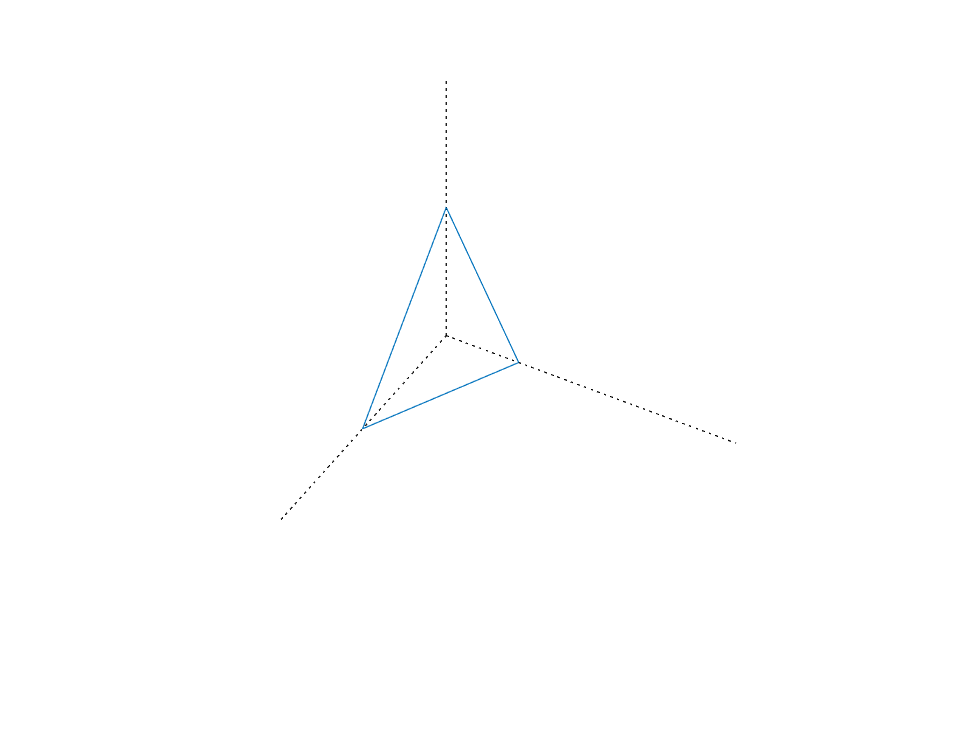

clf                                  
hold on
axis off
axis equal
plot3([4 0 0 4],[ 0 2 0 0],[0 0 4 0])   % plot intersection of plane with the coordinate planes
plot3([0 0],[0 8],[0 0],':k')           % plot positive y-axis
plot3([0 8],[0 0],[0 0],':k')           % plot positive x-axis
plot3([0 0],[0 0],[0 8],':k')           % plot positive z-axis
view(120,40)                            % select viewing point


$$\qquad\qquad\qquad\qquad
\text{solution set:  }\quad
\left\{ ~\left [\matrix{4-2y-z\cr y \cr z}\right]~:~y\in{\mathbb R},~z\in{\mathbb R}\right\}$$


    **Notes:**

- The solution set is parameterized by two free parameters reflecting the solutions set being "two dimensional."

- Plot shows the intersection of the solution set, a plane, with the first octant.

**Example I.2.9: (2 equation with 3 unknowns -- solution line)**


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{\quad
\matrix{
x&+&2y&+&z&=&4\cr
21x&+ &14y &+&6z&=&42} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\qquad
\left[\matrix{
1 & 2 & 1 & 4 \cr
21 & 14 & 6 & 42 }\right]$$


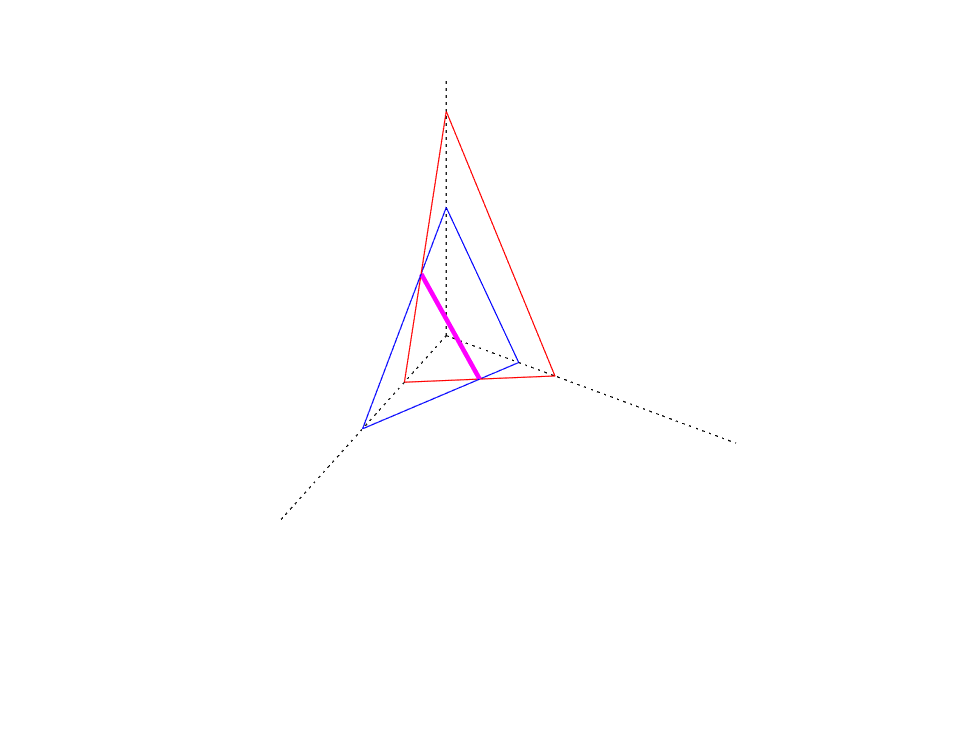

clf 
hold on
axis off
axis equal
plot3([4 0 0 4],[0 2 0 0],[0 0 4 0],'b')   % plot intersection of first plane with coordinate planes (blue)
plot3([2 0 0 2],[0 3 0 0],[0 0 7 0],'r')   % plot intersection of second plane with coordinate planes (red)
plot3([1 6/5],[3/2 0],[0 14/5],'m','LineWidth',2)       % plot intersection of two planes (magenta)
plot3([0 0],[0 8],[0 0],':k')
plot3([0 8],[0 0],[0 0],':k')
plot3([0 0],[0 0],[0 8],':k')
view(120,40)


$$\qquad\qquad\qquad\qquad
\text{solution set:  }\quad
\left\{ ~\left [\matrix{1+\frac{s}{5} \cr \frac32-\frac{3s}{2} \cr \frac{14s}{5}}\right]~:~s\in{\mathbb R}\right\}\quad=\quad
\text{line through } \quad\left[\matrix{1\cr\frac32\cr0}\right]\quad\text{and}\quad
\left[\matrix{\frac65 \cr 0 \cr \frac{14}{5}} \right ]$$


    **Notes:**

- The solution set is a line which is the intersection of two planes.

- The solution set can also be characterized as the line through two points.

- The solution set is parameterized by one free parameter reflecting the solutions set being "one dimensional."

**Example I.2.10: (3 equation with 3 unknowns -- solution point)**


$$\qquad\qquad\qquad\qquad
\text{linear system:}\quad\left\{\quad
\matrix{
x&+&2y&+&z&=&4\cr
21x&+ &14y &+&6z&=&42 \cr
x &+& y &+& 4z &=& 4} \right .
$$



$$\qquad\qquad\qquad\qquad
\text{augmented matrix:  }\qquad
\left[\matrix{
1 & 2 & 1 & 4 \cr
21 & 14 & 6 & 42 \cr
1  & 1 & 4 & 4}\right]$$


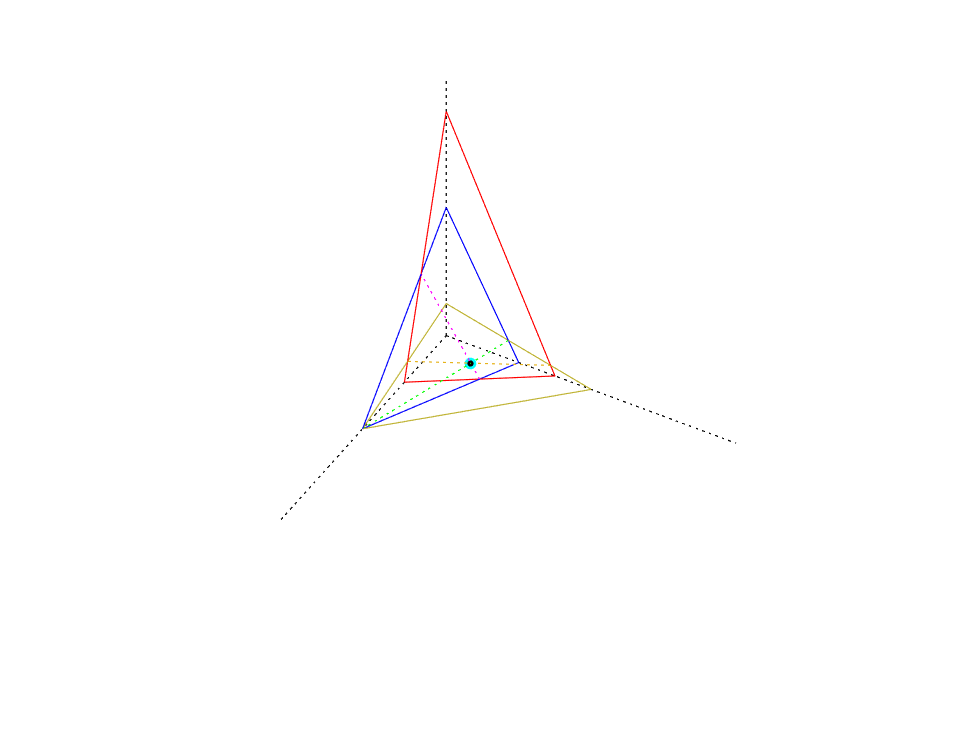

clf 
hold on
axis off
axis equal
plot3([4 0 0 4],[0 2 0 0],[0 0 4 0],'b')    % first equation (blue)
plot3([2 0 0 2],[0 3 0 0],[0 0 7 0],'r')    % second equations (red)
plot3([4 0 0 4],[0 4 0 0],[0 0 1 0],'Color',[0.75 0.7 0.2])    % third equation
plot3([1 6/5],[3/2 0],[0 14/5],':m')        % intersection of first and second equations (magenta)
plot3([4 0],[0 12/7],[0 4/7],':g')          % intersection of first and third equations (green)
plot3([0 24/13],[72/25 0],[7/25 7/13],':','Color',[0.9 0.7 0.1])       % intersection of second and third equations (orange)
plot3(34/33,14/11,14/33,'.c','MarkerSize',15)   % unique solution marked in cyan
plot3(34/33,14/11,14/33,'.k','MarkerSize',8)    % unique solution marked in black
plot3([0 0],[0 8],[0 0],':k')              
plot3([0 8],[0 0],[0 0],':k')
plot3([0 0],[0 0],[0 8],':k')
view(120,40)


$$\qquad\qquad\qquad\qquad
\text{solution set:  }\quad
\left\{ \quad\left [\matrix{\frac{34}{33} \cr \frac{14}{11} \cr \frac{14}{33} }\right]\quad\right\}$$


    **Notes:**

- The solution set, the intersection of three planes, is a singleton set (a set containing one element); i.e., the solution is unique.

## Image Clipping

**The clipping problem.   **A black-and-white computer image consists of a rectangular array of pixels each of which is either black (1) or white (0).    The display of such an image may require clipping, the elimination of pixels outside a region of interest (called the ***clipping region***).     Here we develop a MATLAB function `rclip` to clip a line defined by a linear equation, 

                $\textrm{ax}+\textrm{by}=c$, 

for a clipping region $R\;$consisting of a rectangle aligned with the coordinate axes:

$\qquad\qquad
R~=~\left \{
(x,y)~|~x_\text{min}\le x\le x_\text{max} \quad \text{and}\quad y_\text{min}\le y \le y_\text{max} \right\}$.

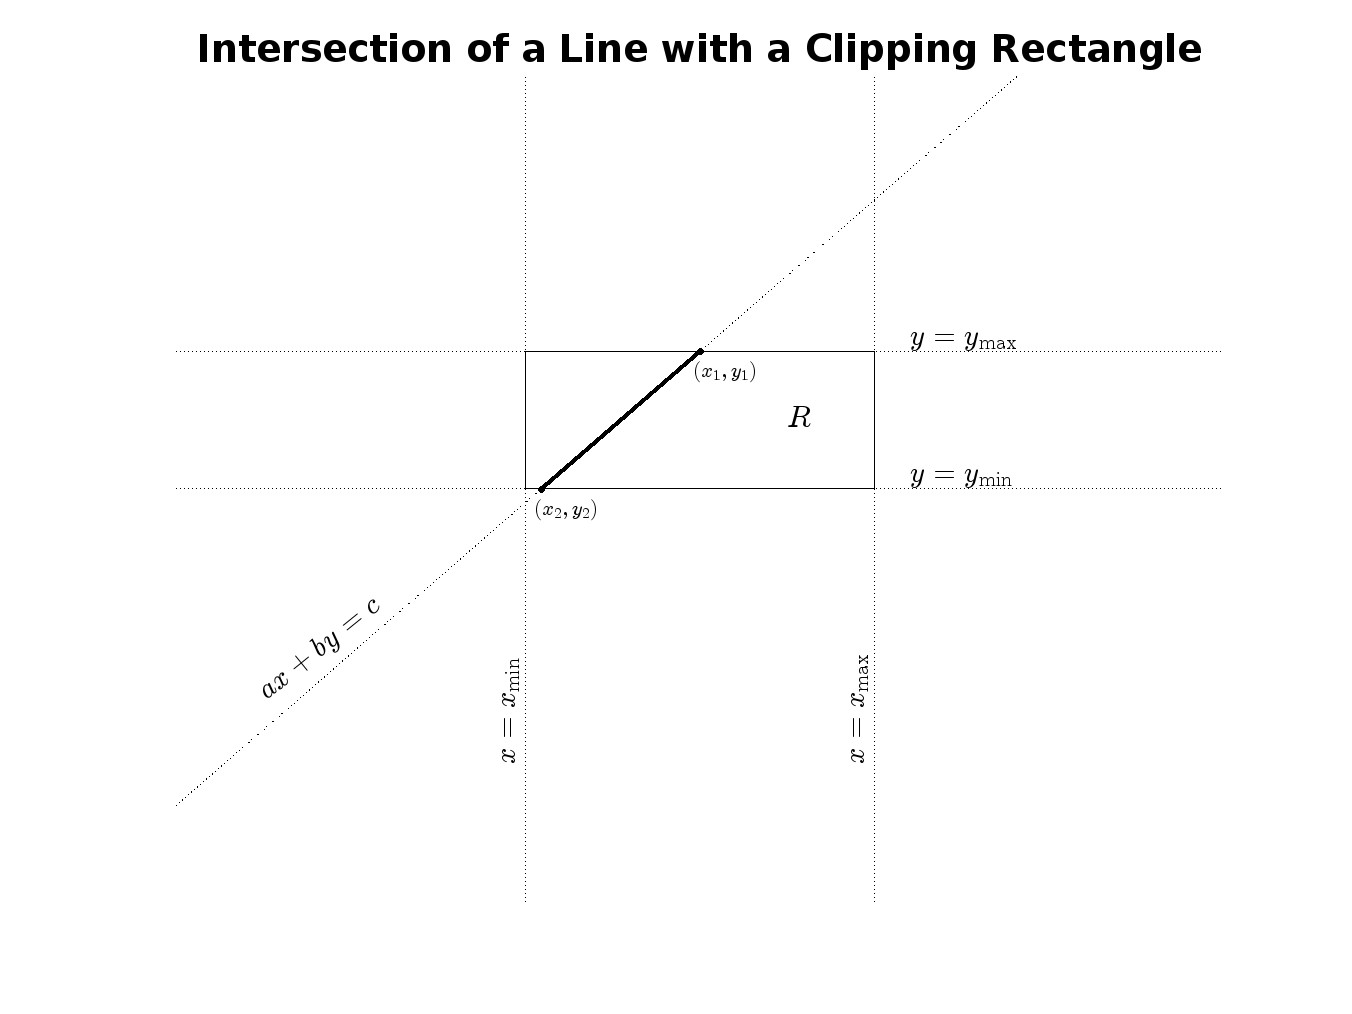

The inputs for our clipping problem are the coefficients and righthand side of the linear equation $a$, $b$ and $c$ and the values defining the clipping rectangle $x_\text{min}$, $x_\text{max}$, $y_\text{min}$ and $y_\text{max}$.  The output is most commonly the endpoints $(x_1,y_1)$ and $(x_2,y_2)$ of the intersection; note, however, the intersection may also be the empty set or a singleton.

**Special cases.   **One prominent feature of this problem is a number of special cases that must be identified and treated separately.    There are quite a few details that must be considered and managed to fully solve the problem.   This situation is typical of the Gaussian elimination algorithm which is the initial focus of the course.    While some of these details may on first examination seem trifling, they often turn out to be of great significance in later applications.     Hence, it is vital to absorb and mentally organize these details to gain full mastery of the subject.

**A parenthetical discussion of lists of vectors.**   In linear algebra, the column vector of length $m
$ (or $m$-vector), a list of $m$ numbers written down the page and generally enclosed in parenthesis or brackets, is one of the main objects of interest.     Here are examples of three 2-vector, two 3-vectors, and a 6-vector:


$$\qquad\qquad
\left[\matrix{1 \cr 2}\right],\quad
\left[\matrix{\pi \cr \sqrt{2}}\right],\quad
\left[\matrix{ 4 \cr -\frac{22}{7}}\right],\quad
\left[\matrix{1 \cr i}\right],\quad
\left[\matrix{1 \cr 2 \cr 0}\right],\quad
\left[\matrix{\frac{22}{7} \cr \sqrt{7} \cr \frac{1+\sqrt{5}}{2}}\right],\quad
\left[\matrix{0\cr1\cr2\cr3\cr4\cr5}\right]$$


These may be entered into MATLAB using square brackets and semicolons:

v1=[1;2], v2=[pi; sqrt(2)], v3=[4; -22/7], v4=[1;i], v5=[22/7; 
sqrt(7);(1+sqrt(5))/2], v6=[0;1;2;3;4;5]

v1 =      1
     2


v2 =     3.1416
    1.4142


v3 =     4.0000
   -3.1429


v4 =    1.0000 + 0.0000i
   0.0000 + 1.0000i


v5 =     3.1429
    2.6458
    1.6180


v6 =      0
     1
     2
     3
     4
     5


It is often useful to arrange a list of m-vectors into a rectangular array (a matrix).     For example, a list consisting of the first three vectors above can be arranged into an array as follows:

array = [v1 v2 v3]

array =     1.0000    3.1416    4.0000
    2.0000    1.4142   -3.1429


Lists, like sets, can be empty, i.e., have no elements.    A convenient way to create an empty list in MATLAB is using the built-in function `zeros. `  The function creates an array of zeros with given dimensions.   For example,

zeros(3,6)     % 3 rows and 6 columns

ans =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


MATLAB allows the number of columns (or rows) to be zero resulting in the creation of an empty list.

emptylist = zeros(2,0)     % an empty list of 2-vectors


emptylist =

  2×0 empty double matrix



The practical importance of the empty list for the clipping problem is that it is possible for a given line to not intersect a given clipping rectangle.    In this case, the list of the endpoints of the segment of intersection is empty and the list returned by `rclip` should of course be empty.   If we neglect to set the list to the empty list MATLAB will likely consider the return variable `list` as undefined resulting in an error.     We avoid this error by carefully distinguishing between an empty array and an undefined array.    

**The intersections of the line **$ax+by=c$ **and the rectangle**$R
$.    Except for the special case $a=b=0$,  the equation $ax+by=c$ defines a line in the plane, and geometric intuition is useful.    There are two basic cases: empty intersection (the line misses the clipping rectangle) and nonempty intersection which we further divide into two distinct subcases of intersection at a single point and intersection in a line segment of infinitely many points.

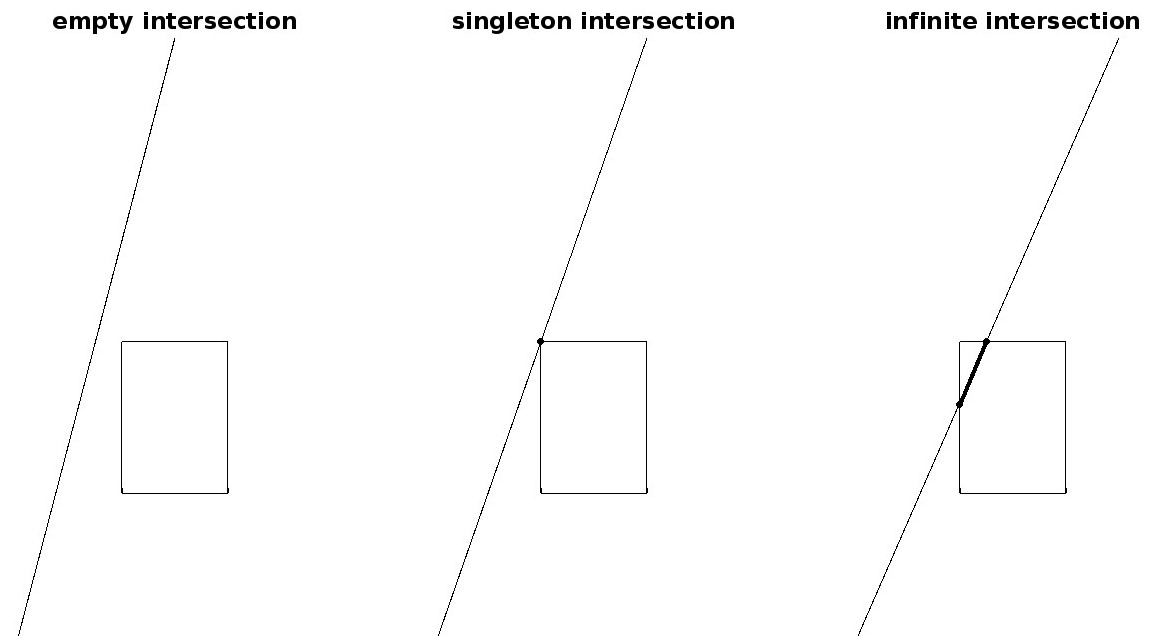

Rectangles have the property that any nonempty intersection with a line is a single line segment (with the possible degenerate case where the endpoints of the segment are the same point).    Hence, the `list` of endpoints returned by `rclip` should consist of 0, 1 or 2 distinct 2-vectors.   For the case where $\textrm{ax}+\textrm{by}=c$ represents a line, we distinguish three subcases:

- $a=0$ and $b\ne0$:   The equation $ax+by=c$ represents the horizontal line $y=\frac{c}{b}$.

- $a\ne 0
$ and $b=0
$:    The equation $ax+by=c$ represents the vertical line $x=\frac{c}{a}$.

- $a\ne 0
$ and $b\ne 0
$:    The equation $ax+by=c$ represents a nonhorizontal/nonvertical line.

From a coding perspective, it is essential to identify which of the coefficients $a$ and $b$ are zero as division by these coefficients is used and division by zero must be avoided. There are four cases that will be handled separately in the code: (0) both coefficients, $a$ and $b$. are zero, (1) only the first coefficient is zero, (2) only the second coefficient is zero and (3) neither coefficient is zero.   The code for `rclip` has the simple structure of identifying which case is implied by the input data and directing MATLAB to execute an appropriate block of code for that case.

**Parenthetical discussion of conditional execution.    **In MATLAB a block of code may be made conditionally executable by preceding it with an `if `statement and terminated with an `end `statement.    An `if` statement consists of the keyword `if` with a condition, a logical expression, which determines whether or not the block is executed.

        `if `*condition*

              *conditionally executed code*

        `end`

Here `condition `is a logical (either true or false) expression that has the logical value of 1 if true and the logical value of 0 if false.   Conditions are commonly derived from one of the following comparison operators:

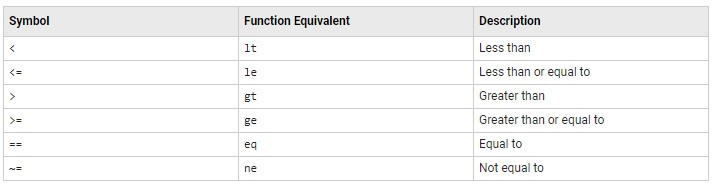

For example, we verity that 3 is greater than 2:

3 > 2

ans = logical
   1


The `condition` also often makes use of logical operators:

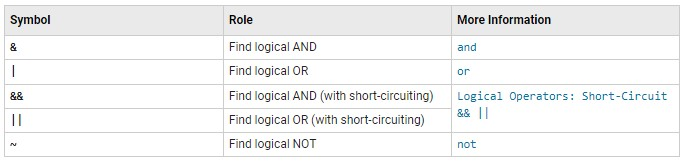

We verify that it is untrue that 3 is greater than 2 and 4 is equal to 5.

3>2 & 4==5

ans = logical
   0


A slightly more complex conditional statement in MATLAB uses the `else` keyword to execute code in case the condition of the if statement is false:

        `if `*condition*

              *code executed if condition is true*

        else 

               *code executed if condition is false*

`    end`

A even more complex conditional statement uses the `elseif` keyword to execute code in the case that the first condition is false and a second condition is true:

        `if `*condition1*

              *code executed if condition1 is true*

        elseif condition2

               *code executed if condition1 is false and condition2 is true*

`    end`

**Writing the code for rclip.   **For the MATLAB function solving our clipping problem, we use the following declaration:

    `function [count, list]=rclip(a,b,c,xmin,xmax,ymin,ymax)`

That is, the values specifying the linear equation and the clipping rectangle are input.    The return values are `count`, an integer indicating the number of endpoints for the intersection of the solution of the linear equation with the clipping rectangle, and `list`, a list of the endpoints.    There are four mutually exclusive cases easily understood geometrically:

- the linear equation fails to define a line ($a=0$ and $b=0$),

- the linear equation defines a horizontal line ($a=0$ and $b\ne0$),

- the linear equation defines a vertical line ($a\ne0
$ and $b=0$),

- the linear equation defines a nonhorizontal/nonvertical line ($a\ne0$ and $b\ne0$).

In the last case, the nonhorizontal/nonvertical line will intersect each of the four lines defining the rectangle (`x=xmin, x=xmax, y=ymin, y=ymax`) in exactly one point.   In this case, we examine each of the intersections and determine which, if any, are on edges of the rectangle.    The first three cases involve either a non-line or a line not intersecting each of the four lines defining the rectangle.

Default return values:   If no intersection is found between a line $\textrm{ax}+\textrm{by}=c$ and the clipping rectangle $E$, then the count of endpoints will be 0 and the list of endpoints will be empty.   It is convenient to set the return values to this default at the beginning of our code; these default values will be modified as needed (such as when endpoints are detected).

`    count = 0;             % zero endpoints`

`    list  = zeros(2,0);    % empty list`

This code is followed by the blocks addressing the different cases:

Case 0:  In the case where the linear equation fails to define a line, there are two subcases.

`    if a==0 && b==0           % linear equation fails to define a line`

`        if c == 0             % solution set is the plane`

`            count = -1;       % return value signaling plane as solution set`

`        else                  % solution set is empty`

`            count = -2;       % return value signaling empty solution set`

`        end`

`        return                % function returns to the caller`

`    end`

These subcases are distinguished by the count returned; the list is empty for both subcases.

[count, list]=rclip(0,0,2,0,1,0,1)     % no solutions of the linear equation

count = -2


list =

  2×0 empty double matrix



Case 1:  In the case of a horizontal line, we determine whether or not the line intersects the left and right sides of the clipping rectangle:

`    if a==0 && b~=0                % if a horizontal line`

`        y = c/b;                   % y value for the horizontal line`

`        if ymin<=y && y<=ymax      % if line intersects sides of the rectangle`

`            count = 2;`

`            list = [xmin xmax; y y];`

`        end`

`        return`

`    end`

`Notice that the expression `y=c/b could be a division by zero were it not for the condition `b~=0`.

[count, list]=rclip(0,2,1,0,1,0,1)    % horizontal line (y=0.5)

count = 2

list =          0    1.0000
    0.5000    0.5000


Case 2:  In the case of a vertical line, we determine whether or not the line intersects the top and bottom sides of the clipping rectangle:

`    if a~=0 && b==0                   % if a vertical line`

`        x=c/a;                        % x value of the vertical line`

`        if xmin<=x && x<=xmax         % if line intersects top and bottom of rectangle`

`            count = 2;            `

`            list = [x x; ymin ymax];`

`        end`

`        return`

`    end`

`Notice that the expression x=c/a `could be a division by zero were not for the condition `a~=0`.

[count, list]=rclip(4,0,1,0,1,0,1)

count = 2

list =     0.2500    0.2500
         0    1.0000


Case 3:  In the case of a nonhorizontal/nonvertical line, we find the four intersections of the line defined by the linear equation with the four lines defining the clipping rectangle and determine whether or not each intersection is on an edge of the rectangle.

`    if a~=0 && b~=0`

`        count = 0;`

`        % check for intersection with left side`

`        y = (c-a*xmin)/b;`

`        if ymin < y && y < ymax`

`            count = count + 1;`

`            list(:,count) = [xmin; y];`

`        end`

`        % check for intersection with right side`

`        y = (c-a*xmax)/b;`

`        if ymin < y && y < ymax`

`            count = count + 1;`

`            list(:,count) = [xmax; y];`

`        end`

`        % check for intersection with top side`

`        x = (c-b*ymax)/a;`

`        if xmin <= x && x <= xmax`

`            count = count + 1;`

`            list(:,count) = [x; ymax];`

`        end`

`        % check for intersection with bottom side`

`        x = (c-b*ymin)/a;`

`        if xmin <= x && x <= xmax`

`            count = count + 1;`

`            list(:,count) = [x; ymin];`

`        end`

`        return`

`    end`

Notice that the left and right edges are not deemed to contain the endpoints of the edges so as to avoid identifying an intersection with a corner as being part of two edges.

### **Follow-up (aka homework)**

**Problem I.2.1:**   The solution set of a single linear equation in two unknowns ($ax+by=p$) is most typically a line in the plane but may also be which of the following sets: (a) the empty set, (b) the entire plane, (c) a single point in the plane, (d) a circle in the plane.

**Problem I.2.2:**   The solution set of a system of two linear equations in two unknowns 

                                                            
$$\left\{ \matrix{ax&+&by&=&p\cr cx&+&dy&=&q} \right.$$


is most typically a point in the plane but may also represent which of the following sets:  (a) the empty set, (b) the entire plane, (c) a single point in the plane, (d) a circle in the plane.

**Problem I.2.3:**  The solution set of the linear system

                                                            
$$\left\{ \matrix{3x&+&6y&=&3\cr 1x&+&2y&=&9} \right.$$


is (a) the empty set, (b) the point $(x,y)=(3,3)$, (c) the line $x+2y=1$, (d) the entire plane.

**Problem I.2.4:**  The solution set of the linear system

                                                            
$$\left\{ \matrix{x&+&3y&+&2z&=&1\cr 2x&+&6y&+&5z&=&1} \right.$$


is (a) the empty set, (b) the point $(x,y,z)=(3,0,-1)$, (c) the line $(x,y,z)=(3-3s,s,-1)$, (d) the plane $(x,y,z)=(1-3s-2t,s,t)$.

**Problem I.2.5:**  The solution set of the linear system

                                                            
$$\left\{ \matrix{x&+&y&=&4\cr 3x&+&2y&=&11\cr
2x&-&4y&=&2} \right.$$


is (a) the empty set, (b) the point $(x,y)=(3,1)$, (c) the line $6x-y=17$, (d) the entire plane.

**Problem I.2.6:  **Which of the following linear systems have solutions sets with exactly one element?

    (a)     $\left\{ \matrix{6x&+&6y&=&3\cr 1x&+&2y&=&9} \right.$

    (b)     $\left\{ \matrix{6x&+&6y&+&3z&=&3\cr 1x&+&2y&+&7z&=&9} \right.$

    (c)      $\left\{ \matrix{6x&=&3} \right.$

    (d)     $\left\{ \matrix{x&+&y&+&z&=&3\cr &&2y&+&2z&=&9\cr
& & & & 4z&=&8} \right.$

    (e)    $\left\{ \matrix{6x&+&6y&=&3\cr 2x&+&2y&=&9} \right.$

**Problem I.2.7:  **Which are the $x$-, $y$-, and $z$- intercepts of the plane $8x+3y+48z=24$?

    (a) 8, 3 and 48

    (b) 3, 8 and 2

    (c) 1/3, 1/8 and 2

    (d) 3,8 and 1/2

**Problem I.2.8:  **Let $U=\left\{(x,y)~:~0\le x\le1\quad\text{and}\quad
0\le y\le1\right\} $.  The intersection of $U$ with the line $3y-6x=1$is 

    (a)    the empty set,

    (b)    the single point (0,1),

    (c)    the line segment with endpoints (-1/6,0) and (1,7/3),

    (d)    the line segment with endpoints (0,1/3) and (1/3,1),

    (e)    the entire plane.

**Problem I.2.9:    **Let $U=\left\{(x,y)~:~0\le x\le1\quad\text{and}\quad
0\le y\le1\right\} $.  The intersection of $U$ with the line$14x-y=-14$ is 

    (a)    the empty set,

    (b)    the single point (1,0),

    (c)    the line segment with endpoints (0,1) and (1,0),

    (d)    the line segment with endpoints (1,0) and (15/14,1),

    (e)    the entire plane.

**Problem I.2.10:   **Let $U=\left\{(x,y)~:~0\le x\le1\quad\text{and}\quad
0\le y\le1\right\} $.  The intersection of $U$ with the line$7x+y=14$ is 

    (a)    the empty set,

    (b)    the single point (1,1),

    (c)    the line segment with endpoints (13/14,1) and (1,2/7),

    (d)    the line segment with endpoints (1,0) and (15/14,1),

    (e)    the entire plane. 

**Problem I.2.11:**   What is the output of the following MATLAB code?

`    x=1;`

`    y=2;`

`    if x>y`

`        x+y`

        `elseif x==y`

`        x-y`

`    elseif x<y`

`        x*y`

`    end`

**Problem I.2.12:**   What is the output of the following MATLAB code?

    (1==1)*(1~=0)*(2>1)*(1<2)

#### MATLAB Assignment 1:  A Clipping Triangle

MATLAB Assignment 1 requires completion of code, similar to `rclip.m (below)`, to determine the endpoints of the intersection of a line with a triangle.   

#### Appendix I2.1:   MATLAB Functions

function [count, list] = rclip(a,b,c,xmin,xmax,ymin,ymax)

% [count list] = rclip(a,b,c,xmin,xmax,ymin,ymax)
%
% count is the number of intersections of the line ax+by=c with
%       the boundary of the rectangle [xmin,xmax]x[ymin,ymax] unless
%       the equation ax+by=c defines an empty set (count=-2) or the 
%       entire plane (count=-1).
%
% list is a 2xmax(0,count) matrix where each column is a point of 
%       intersection of the line with the boundary of the rectangle.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  The four cases below are mutually exclusive.   That is, only one
%  is expected to be executed.    The fourth case, however, has
%  four subcases which are not mutually exclusive.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%  Case 0:   a==0  and b==0 (no line defined)

    if a==0 && b==0      

        if c == 0        % solution set is the plane
            count = -1;
        else             % solution set is empty
            count = -2; 
        end
        
        list = zeros(2,0);    %empty list
        
        return
    end

%  Case 1: a==0 and b~=0 (horizontal line)

    if a==0 && b~=0
        y = c/b;
        if ymin<=y && y<=ymax
            count = 2;
            list = [xmin xmax; y y];
        else
            count = 0;
            list = zeros(2,0);    %empty list
        end
        return
    end


%  Case 2:   a~=0   and b==0 (vertical line)

    if a~=0 && b==0
        x=c/a;
        if xmin<=x && x<=xmax
            count = 2;
            list = [x x; ymin ymax];
        else
            count = 0;
            list = zeros(2,0);    %empty list
        end
        return
    end

%   Case 3:    a~=0   and   b~=0 (non-horizontal/non-vertical line)

    if a~=0 && b~=0

        count = 0;

        % check intersection with left side

        y = (c-a*xmin)/b;

        if ymin < y && y < ymax
            count = count + 1;
            list(:,count) = [xmin; y];
        end

        % check intersection with right side

        y = (c-a*xmax)/b;

        if ymin < y && y < ymax
            count = count + 1;
            list(:,count) = [xmax; y];
        end

        % check intersection with top side

        x = (c-b*ymax)/a;

        if xmin <= x && x <= xmax
            count = count + 1;
            list(:,count) = [x; ymax];
        end

        % check intersection with bottom side

        x = (c-b*ymin)/a;

        if xmin <= x && x <= xmax
            count = count + 1;
            list(:,count) = [x; ymin];
        end

        return
    end

    'UNREACHABLE CODE'
end

function plot2unknowns(aug,win,en)
% Plots equation with augmented matrix aug in the window win and lables the
% example as en
    [m, n]=size(aug);
    if n ~= 3
        'Number of unknowns must be 2'
        return
    end
    clf
    axis equal
    axis(win)
    hold on
    plot([0 0],win([3 4]),':k')
    plot(win([1 2]),[0 0],':k')

    for ell= 1:m
        [count, list] = rclip(aug(ell,1),aug(ell,2),aug(ell,3),win(1),win(2),win(3),win(4));
        if count == 2
            plot(list(1,:),list(2,:),'b')
        end
    end
    titletext = sprintf('Example #%d',en);
    title(titletext)

end
